close all
clc
clear all
load ARTEMIS.mat;
load ARTEMIS_road.mat
load WLTC.mat
load eff_interpol.mat

my_cycle(1,:)=linspace(30,0,1001);
my_cycle(2,:)=[my_cycle(1,1:end-1)-my_cycle(1,2:end),0];
my_cycle(3,:)=3;

start=0;%Definisci l'istante iniziale
N=5; %Time horizon ->compare sol with 5
SOC_START=0.55;

SOC=SOC_START*ones(N,1);
u_n=1*ones(N,1);
N_rounds=1;
driving_cycle=ARTEMIS_road;
N_it=length(driving_cycle)-1;



u=zeros(1,N_it*N_rounds);
eltime = 0;
tic
x=zeros(N_rounds,1);
C=[eye(N);-eye(N)];
d=[-ones(N,1);-ones(N,1)];

myoptions               =   myoptimset;
myoptions.Hessmethod  	=	'BFGS';
myoptions.gradmethod  	=	'CD';
myoptions.graddx        =	2^-17;
myoptions.tolgrad    	=	1e-6;
myoptions.tolfun    	=	1e-12;
myoptions.tolX       	=	1e-12;
myoptions.ls_beta       =	0.2;
myoptions.ls_c          =	.01;
myoptions.ls_nitermax   =	1e2;
myoptions.nitermax      =	1e2;
myoptions.tolconstr     =	1e-3;
myoptions.xsequence     =	'on';
myoptions.display       ='none';
        %%

for k=1:N_rounds
     %Se si vuole cambiare ciclo tra un round e l'altro
     %x(k)=rand;
     %driving_cycle=(x(k)<0.33)*ARTEMIS+(x(k)>=0.33)*ARTEMIS_road*(x(k)<=0.66)+(x(k)>0.66)*my_cycle;
    for j=1:N_it-N
        %Estrai i sottovettori e ridefinisci gli handle per i sottovettori.
        %Stavolta la funzione di costo è calcolata tutta in una volta. Bisogna
        %rivedere la funzione di costo bene
       
        speed=driving_cycle(1,start+j:start+N-1+j);
        acceleration=driving_cycle(2,start+j:start+N-1+j);
        gear=driving_cycle(3,start+j:start+N-1+j);
        
        StateUpdate=@(input,cur_SOC,i)my_hev(speed(i),acceleration(i),gear(i),cur_SOC,input,etam_int,etaeng_int,Tmmax_int,Tmmin_int,Temax_int);
        myFullStateUpdate=@(u)my_full_horizon(u,SOC(2),StateUpdate);
        FullStateUpdate=@(u)full_horizon(u,SOC(2),StateUpdate);
        
        %calcoli la u ottima sull'orizzonte dei 5 secondi
        [u_n,~,~,exitf(j),~,~]=myfmincon(myFullStateUpdate,[u_n(2:end);u_n(end)],[],[],C,d,0*N,8*N,myoptions);
        if exitf(j)<=0
            [u_n,~,~,exitf(j),~,~]=myfmincon(myFullStateUpdate,[u_n(2:end);0.4],[],[],C,d,0*N,8*N,myoptions);
        end

        %salvi la u per poi vedere il risultato complessivo
        u(j+(k-1)*N_it)=u_n(1);
        if exitf(j)<=0
            fprintf("All'iterazione %d l'exitflag è %d ",j,exitf(j))
        end
    
        if rem(j,N_it/10)==0
            eltime = eltime+toc;
            fprintf("Siamo al: %f percento del giro %d \n Ci ha messo %f \n",j/(N_it)*100,k,toc)
            tic
        end
    
        [~,SOC]=FullStateUpdate(u_n);
    end
end

Siamo al: 10.000000 percento del giro 1 
 Ci ha messo 4.825616 
Siamo al: 20.000000 percento del giro 1 
 Ci ha messo 3.670016 
Siamo al: 30.000000 percento del giro 1 
 Ci ha messo 5.907721 
Siamo al: 40.000000 percento del giro 1 
 Ci ha messo 10.147574 
Siamo al: 50.000000 percento del giro 1 
 Ci ha messo 4.909989 
Siamo al: 60.000000 percento del giro 1 
 Ci ha messo 4.435101 
Siamo al: 70.000000 percento del giro 1 
 Ci ha messo 1.693667 
Siamo al: 80.000000 percento del giro 1 
 Ci ha messo 4.079334 
Siamo al: 90.000000 percento del giro 1 
 Ci ha messo 2.490495 


fprintf("Mediamente ci ha messo %f secondi ad iterazione \n",eltime/N_it)

Mediamente ci ha messo 0.042159 secondi ad iterazione 


toc

Elapsed time is 4.604188 seconds.


%Vedi i risultati utilizzando la u trovata nell'intero orizzonte
speed=[];
acceleration=[];
gear=[];

for i=1:54
    %driving_cycle=(x(i)<0.33)*ARTEMIS+(x(i)>=0.33)*ARTEMIS_road*(x(i)<=0.66)+(x(i)>0.66)*my_cycle;
    speed=[speed,driving_cycle(1,start+1:start+N+j)];
    acceleration=[acceleration,driving_cycle(2,start+1:start+N+j)];
    gear=[gear,driving_cycle(3,start+1:start+N+j)];
end
StateUpdate=@(input,cur_SOC,i)my_hev(speed(i),acceleration(i),gear(i),cur_SOC,input,etam_int,etaeng_int,Tmmax_int,Tmmin_int,Temax_int);
FullStateUpdate=@(u)full_horizon(u,SOC_START,StateUpdate);
[cost,SOC2plot,T_req,T_giv,mf,I_c,V_c,Tm]=FullStateUpdate(u);
[c,ceq]=nonlinconstr(u,SOC_START,StateUpdate);
tot_c=sum(sum(c<=0))/(4*length(c))

tot_c = 0.5000

tot_ceq=sum(abs(ceq)<=myoptions.tolconstr)/length(ceq)

tot_ceq = 0.9430

tot_mf=sum(mf)*1000

tot_mf = 88.4510

tot_soc_var=SOC_START-SOC(end)

tot_soc_var = 0.0326

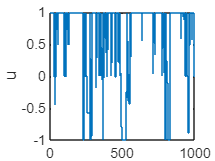

stairs(u)
ylabel('u')

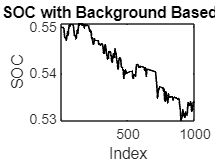

figure
hold on
num_segments = length(x); % Number of regions
segment_size = length(SOC) / num_segments; % Elements per segment
colors = [1 1 0; 1 0 0; 0 1 0]; % Define colors (red, green, blue)

% for i = 1:num_segments
%     % Define segment range
%     x_start = (i - 1) * segment_size + 1;
%     x_end = i * segment_size;
% 
%     % Determine background color based on x(i)
%     if x(i) < 0.33
%         bg_color = colors(1, :); % Light red
%     elseif x(i) < 0.66
%         bg_color = colors(2, :); % Light green
%     else
%         bg_color = colors(3, :); % Light blue
%     end
% 
%     % Plot background as a filled rectangle
%     fill([x_start x_end x_end x_start], [min(SOC) min(SOC) max(SOC) max(SOC)], ...
%         bg_color, 'EdgeColor', 'none');
% end

% Plot the SOC data on top
plot(SOC2plot, 'k', 'LineWidth', 1);

% Additional plot settings
xlim([1, length(SOC2plot)]);
ylim([min(SOC2plot), max(SOC2plot)]);
xlabel('Index');
ylabel('SOC');
title('SOC with Background Based on x');
box on;
hold off

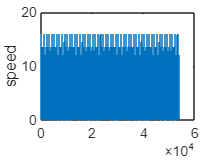


stairs(speed)
ylabel('speed')

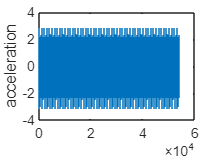

stairs(acceleration)
ylabel('acceleration')

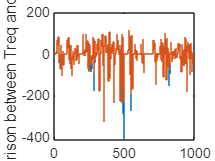

stairs(T_giv)
hold on
stairs(T_req)
hold off
ylabel('comparison between Treq and Tgiven')